%% STEP 0: Load and isolate India
emissions = readtable('GCB2024v18_MtCO2_flat.csv');


% Keep only India data from 1858 onward (where measurements begin)
india = emissions(strcmp(emissions.Country,"India") & emissions.Year >= 1858, :);

% Display raw data
disp("India data before cleaning:")

India data before cleaning:


disp(india(1:10,:))

     Country     ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita
    _________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________

    {'India'}        {'IND'}          356     1858    0.39449    0.39449      0      0     NaN        NaN       NaN     0.001631 
    {'India'}        {'IND'}          356     1859    0.63648    0.63648      0      0     NaN        NaN       NaN     0.002623 
    {'India'}        {'IND'}          356     1860    0.64311    0.6431


%% STEP 1: Clean data (replace zeros with NaN in numeric columns)
india_clean = india;

numCols = varfun(@isnumeric, india_clean, 'OutputFormat','uniform');

% Exclude Total from zero-to-NaN conversion
numCols(strcmp(india_clean.Properties.VariableNames,'Total')) = false;

X = india_clean{:,numCols};
X(X == 0) = NaN;
india_clean{:,numCols} = X;

disp("India data after replacing 0 with NaN:")

India data after replacing 0 with NaN:


disp(india_clean(1:10,:))

     Country     ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita
    _________    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________

    {'India'}        {'IND'}          356     1858    0.39449    0.39449    NaN    NaN     NaN        NaN       NaN     0.001631 
    {'India'}        {'IND'}          356     1859    0.63648    0.63648    NaN    NaN     NaN        NaN       NaN     0.002623 
    {'India'}        {'IND'}          356     1860    0.64311    0.6431

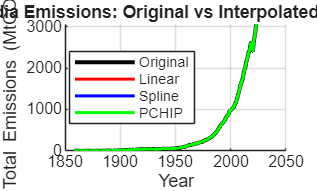


%% STEP 2: Interpolation
cols = {'Coal','Oil','Gas','Cement','Flaring'};

% Copy tables
india_linear = india_clean;
india_spline = india_clean;
india_pchip  = india_clean;

% Interpolate NaNs only
india_linear{:,cols} = fillmissing(india_clean{:,cols}, 'linear', 'EndValues','none');
india_spline{:,cols} = fillmissing(india_clean{:,cols}, 'spline', 'EndValues','none');
india_pchip{:,cols}  = fillmissing(india_clean{:,cols}, 'pchip',  'EndValues','none');

%% STEP 3: Recompute totals after interpolation
india_linear.Total = sum(india_linear{:,cols}, 2, 'omitnan');
india_spline.Total = sum(india_spline{:,cols}, 2, 'omitnan');
india_pchip.Total  = sum(india_pchip{:,cols}, 2, 'omitnan');

%% STEP 4: Extract series for plotting
years        = india.Year;
orig_total   = india.Total;
linear_total = india_linear.Total;
spline_total = india_spline.Total;
pchip_total  = india_pchip.Total;

%% STEP 5: Plot combined comparison
figure;
hold on;
plot(years, orig_total,   'k-', 'LineWidth', 2,   'DisplayName','Original');
plot(years, linear_total, 'r-', 'LineWidth', 1.5, 'DisplayName','Linear');
plot(years, spline_total, 'b-', 'LineWidth', 1.5, 'DisplayName','Spline');
plot(years, pchip_total,  'g-', 'LineWidth', 1.5, 'DisplayName','PCHIP');
hold off;

xlabel('Year');
ylabel('Total Emissions (MtCO_2)');
title('India Emissions: Original vs Interpolated Totals');
legend('Location','best');
grid on;

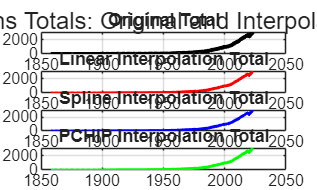


%% STEP 6: Plot separately (diagnostics)
figure;

subplot(4,1,1)
plot(years, orig_total, 'k-', 'LineWidth', 2);
title('Original Total'); grid on;

subplot(4,1,2)
plot(years, linear_total, 'r-', 'LineWidth', 1.5);
title('Linear Interpolation Total'); grid on;

subplot(4,1,3)
plot(years, spline_total, 'b-', 'LineWidth', 1.5);
title('Spline Interpolation Total'); grid on;

subplot(4,1,4)
plot(years, pchip_total, 'g-', 'LineWidth', 1.5);
title('PCHIP Interpolation Total'); grid on;

sgtitle('India Emissions Totals: Original and Interpolation Methods');


% Save cleaned data
save('India_Emissions_Cleaned.mat', 'india_linear');